clear all

set(0, 'DefaultTextFontSize', 12) % modify it if too small
set(0, 'DefaultAxesFontSize', 11) % modify it if too small
set(0, 'DefaultLegendFontSize', 12) % modify it if too small
set(0, 'DefaultAxesXGrid', 'on')
set(0, 'DefaultAxesYGrid', 'on')
set(0, 'DefaultLegendInterpreter', 'latex')
set(0, 'DefaultAxesTickLabelInterpreter', 'latex')
set(0, 'DefaultTextInterpreter', 'latex')
set(0, 'defaultLineLineWidth', 1.2)
colors = [0    50   71;... % (1) DEEP SPACE
          207  29   57;... % (2) EXCITE RED +1
          0    142  122;... % (3) PURE TEAL +1
          251  171  24;... % (4) ENLIGHT YELLOW
          244  121  32;... % (5) ENLIGHT YELLOW +1
          150  1    54;... % (6) EXCITE RED +2
          167  85   52;... % (7) ENLIGHT YELLOW +2
          0    97   158;... % (8) TRUSTY AZURE +1
          30   51   120;... % (9) TRUSTY AZURE +2
          0    103  98;... % (10) PURE TEAL +2
          51   94   111;... % (11) DEEP SPACE -1
          0    0    0]./255; % (12) BLACK

## Infinite Horizon Control (LQR) Deployment from 2km on Ast-Earth line

%PWPF modulator parameter
d_lp=0.6;%0.6
d_lp_z=10;
d_lp_sk=0.6;
n_lp=2.4;%20;
n_lp_z=30;%11;
n_lp_sk=30;

a=0.78*astroConstants(2);
time_sim=3600;%2*pi*sqrt((a^3)/astroConstants(4));
e=0.3;
n=sqrt(astroConstants(4)/(a^3));
teta_0=deg2rad(0);
k= 100;%-83.33333 %to change the size of the regular orbit
dteta=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5)*k;
%reference_conds=[-20,0];
r_target=2;
perturbed=true;
if perturbed
    v_x_perturbation=0.0001; %km/s
    v_y_perturbation=0;%0.0001/sqrt(3); %km/s
    v_z_perturbation=0;%.0001/sqrt(3); %km/s
    init_conds=[v_x_perturbation -2 v_y_perturbation 0];
    init_conds_z=[v_z_perturbation 0];
else
    init_conds=[0 -2 0 0];
    init_conds_z=[0 0];
end

T=[dteta^2 dteta*(-(n*2*(1+e*cos(teta_0))*e*sin(teta_0)/((1-e^2)^1.5))) 0 0; 0 dteta 0 0; 0 0 dteta^2 dteta*(-(n*2*(1+e*cos(teta_0))*e*sin(teta_0)/((1-e^2)^1.5))); 0 0 0 dteta];
true_anom=teta_0;
A_ss=[ 2*e*sin(true_anom)/(1+e*cos(true_anom)), (3+e*cos(true_anom))/(1+e*cos(true_anom)), 2, -2*e*sin(true_anom)/(1+e*cos(true_anom)); 
    1, 0, 0, 0;
   -2, 2*e*sin(true_anom)/(1+e*cos(true_anom)), 2*e*sin(true_anom)/(1+e*cos(true_anom)), e*cos(true_anom)/(1+e*cos(true_anom));
   0, 0, 1, 0];
B_ss=((1-(e^2))^3)/(((1+e*cos(true_anom))^4)*(n^2))*[1 0; 0 0; 0 1; 0 0];
T_inv=[1/dteta 0 0 0; 0 1 0 0; 0 0 1/dteta 0; 0 0 0 1];
C=[0 1 0 0; 0 0 0 1]; %VELOCITY CHANGED
A=T*A_ss*T_inv;
B=T*B_ss;
Wzz=[1 0; 0 1];%eye(2);
Q=C'*Wzz*C;
R=10000000;
K=lqr(A,B,Q,R);

M=-inv(C*inv(A-B*K)*B)

M = 	1.0e+-3 *

    0.3162   -0.0000
    0.0000    0.3162




% control for z
T_z=[dteta^2 dteta*(-(n*2*(1+e*cos(teta_0))*e*sin(teta_0)/((1-e^2)^1.5))); 0 dteta];
A_ss_z=[2*e*sin(true_anom)/(1+e*cos(true_anom)) -1/(1+e*cos(true_anom)); 1 0];
B_ss_z=((1-(e^2))^3)/(((1+e*cos(true_anom))^4)*(n^2))*[1; 0];
T_inv_z=[1/dteta 0 ; 0 1];
C_z=[0 1]

C_z =      0     1


A_z=T_z*A_ss_z*T_inv_z

A_z =          0   -0.0000
    1.0000         0


B_z=T_z*B_ss_z;
Wzz_z=1;
Q_z=C_z'*Wzz_z*C_z;
R_z=100000000;
K_z=lqr(A_z,B_z,Q_z,R_z);
M_z=-(C_z*inv(A_z-B_z*K_z)*B_z)\1;

Run Simulink:

sim_out_HC=sim('relative_dynamics_Earth_SK.slx');

Plotting the results:

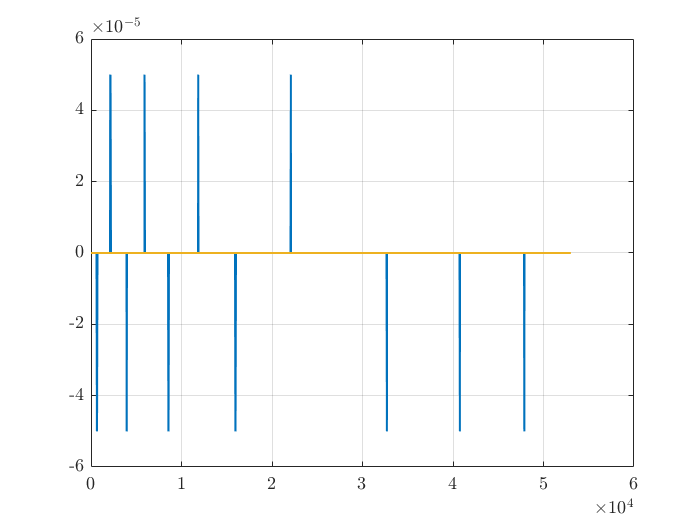

figure()
plot(sim_out_HC.thrust.time, sim_out_HC.thrust.data(:,1))
hold on

plot(sim_out_HC.thrust.time, sim_out_HC.thrust.data(:,2))
plot(sim_out_HC.thrust_z.time, sim_out_HC.thrust_z.data(:,1))
hold off

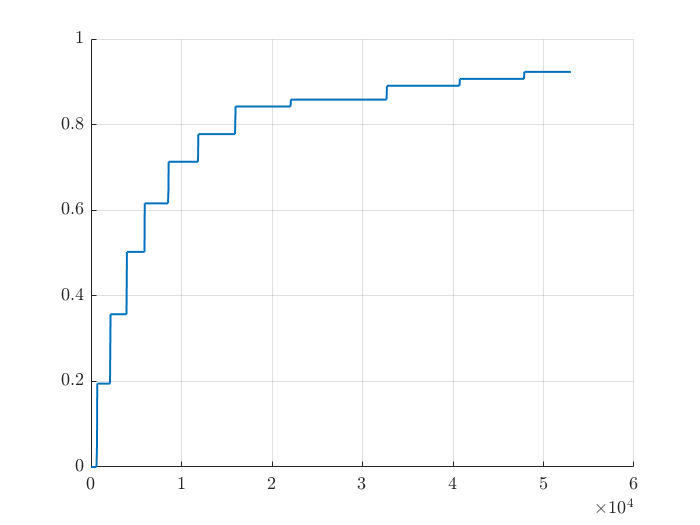


figure()
% plot(sim_out_HC.simout.Data(:,2),sim_out_HC.simout.Data(:,4))
hold on
% plot(sim_out_HC.delta_v.time,sim_out_HC.delta_v.Data(:))

plot(sim_out_HC.deltav_z.time,(sim_out_HC.deltav_z.Data(:)+sim_out_HC.deltav.Data(:)).*(1000))
hold off


% ricorda hai cambiato ton when PWPFM di 1 odg, considera pert velocità
% come velocità di discesa